# Calculating ensemble KE spectral

Reference: Weyn and Durran (2017)

### 
$$\widehat{KE_m } \left(k_h \right)=\frac{\Delta x\Delta y\Delta z}{8\pi^2 n_x n_y }\left\lbrack \hat{u_m } \left(k_h \right)\hat{u_m^* } \left(k_h \right)+\hat{v_m } \left(k_h \right)\hat{v_m^* } \left(k_h \right)\right\rbrack$$


m: member

$k_h$: wave number ($k_h =\frac{2\pi }{L}n\;,n=1,2,3,4\ldotp \ldotp \ldotp \ldotp$)  L: domain size (km)

Total KE: mean of each member's KE

Perturbation KE: use u' = u-$\overline{u}$ of each member instead of u

### Settings 

clear
%---setting
expri='ens02';  member=10;
%year='2007'; mon='06'; date='01';
year='2018'; mon='06'; date='22';  hr=0;  minu=0;
dirmem='pert'; infilenam='wrfout';  dom='01';

indir=['E:/wrfout/expri_ens200323/',expri];
outdir='E:/figures/expri191009/';
titnam='KE spectral';   fignam=[expri,'_KE-sp_'];

### Read WRF file

ti=hr; tmi=minu;  mi=member;
%---set filename---
s_hr=num2str(ti,'%.2d');  % start time string
s_min=num2str(tmi,'%.2d');
nen=num2str(mi,'%.2d');
infile=[indir,'/',dirmem,nen,'/',infilenam,'_d',dom,'_',year,'-',mon,'-',date,'_',s_hr,'%3A',s_min,'%3A00'];
%------read netcdf data--------
u.stag = ncread(infile,'U');u.stag=double(u.stag);
v.stag = ncread(infile,'V');v.stag=double(v.stag);
%---
u.unstag=(u.stag(1:end-1,:,:)+u.stag(2:end,:,:)).*0.5;
v.unstag=(v.stag(:,1:end-1,:)+v.stag(:,2:end,:)).*0.5;

### 2-D fast Fourier transform

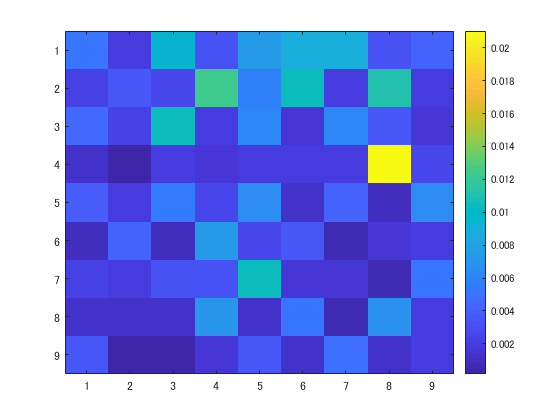

lev=1;  
u.ori=u.unstag(:,:,lev); 
v.ori=v.unstag(:,:,lev);
[nx, ny]=size(u.ori);
u.fft=fft2(u.ori)/(nx*ny);
v.fft=fft2(v.ori)/(nx*ny);
imagesc(abs(v.fft(2:10,2:10)))   % u.fft(1,1)/(nx*ny)=mean(mean(u.ori))
colorbar

### KE spectral

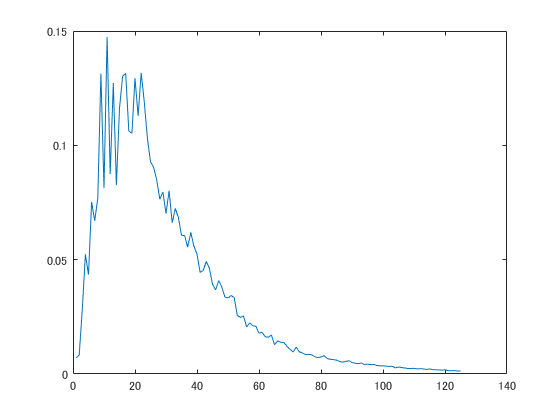


dx=1; dy=1;
Lx=dx*nx;  Ly=dy*ny;
dk=2*pi/Lx;
KE=(abs(u.fft(2:Lx/2,2:Ly/2))+abs(v.fft(2:Lx/2,2:Ly/2)));

KE_h=zeros(125,1);
for xi=1:Lx/2-1
    for yi=1:Ly/2-1
        n=(xi^2+yi^2)^0.5;
        for ki=1:max(Lx,Ly)/2
            if (n>ki-0.5 && n<=ki+0.5)
                KE_h(ki)=KE(xi,yi)+KE_h(ki);
            end
        end
    end
end


 figure 
plot(KE_h(1:125))